## AAE 364 HW11

clear all; close all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Spring\AAE364\matlab\matlab_output\hw12';
set(groot, 'defaulttextinterpreter','latex');  
set(groot, 'defaultAxesTickLabelInterpreter','latex');  
set(groot, 'defaultLegendInterpreter','latex');

% Bode plot options
opts_bd = bodeoptions('cstprefs');
opts_bd.Title.Interpreter = "latex";
opts_bd.XLabel.Interpreter = "Latex";
opts_bd.YLabel.Interpreter = "Latex";
opts_bd.Grid = 'on';

% Nyquist plot options
opts_nq = nyquistoptions("cstprefs");
opts_nq.Title.Interpreter = 'latex';
opts_nq.XLabel.Interpreter = "Latex";
opts_nq.YLabel.Interpreter = "Latex";
opts_nq.Grid = 'on';

### B-7-14

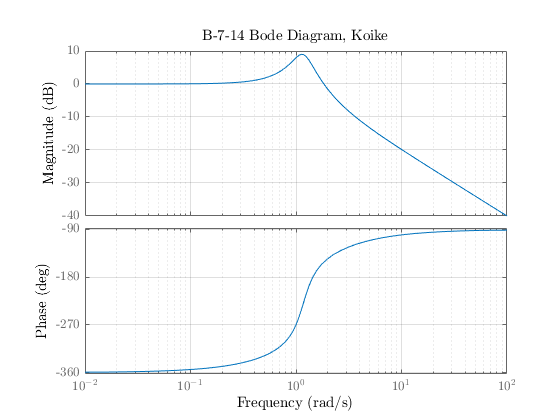

% Define transfer function
num = [1 2 1];
den = [1 0.2 1 1];
G = tf(num,den);

% Find zeros, poles, and corner frequencies
zrs = roots(num);
pls = roots(den);
cornFreq = corner_freq(num,den);

% Bode Plot
fig = figure("Renderer","painters");
    opts_bd.Title.String = "B-7-14 Bode Diagram, Koike";
    bd = bodeplot(G,opts_bd);
    opt = getoptions(bd);
saveas(fig,fullfile(fdir,"B-7-14_bode.png"));

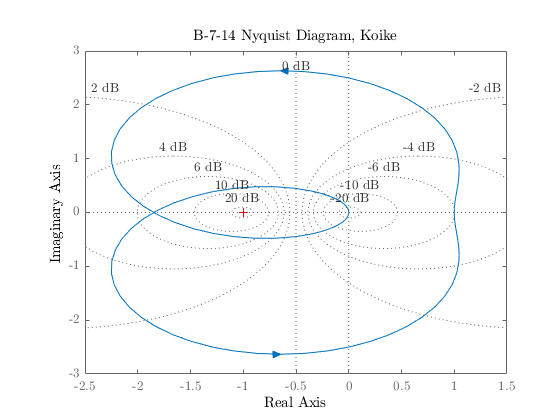


% Sample out points from Bode plot
res = bode_sample_points(G,[0.05,0.4,1,4,10]);
writetable(res,fullfile(fdir,"B-7-14.xls"),"WriteMode","overwrite");

% Nyquist Plot 
fig = figure("Renderer","painters");
    opts_nq.Title.String = "B-7-14 Nyquist Diagram, Koike";
    nyquistplot(G,opts_nq);
saveas(fig,fullfile(fdir,"B-7-14_nyquist.png"));


% Calculate the intersection with the real axis
[Wpc,intrsct_Re] = phase_crossover(num,den);

The denominator factored out.


$$-1.0\,w^{3}\,\mathrm{i}-0.2\,w^{2}+1.0\,w\,\mathrm{i}+1.0$$

The numerator combined with denominator.


$$-1.0\,\left(-1.0\,w^{2}+2.0\,w\,\mathrm{i}+1.0\right)\,\left(-1.0\,w^{3}\,\mathrm{i}+0.2\,w^{2}+1.0\,w\,\mathrm{i}-1.0\right)$$

The imaginary part you need to equate to 0.


$$\left(w-1.0\,w^{3}\right)\,\left(w^{2}-1.0\right)-2.0\,w\,\left(0.2\,w^{2}-1.0\right)$$

Omegas that make the imaginary part equal 0 (phase crossover frequency).
         0
    1.4424
   -1.4424



### B-7-15

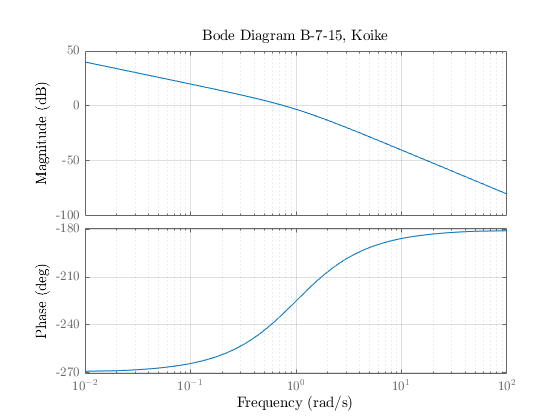

num = [0 1];
den = conv([1 0],[1 -1]);
G = tf(num,den);
% Bode plot
fig = figure("Renderer","painters");
    opts_bd.Title.String = "Bode Diagram B-7-15, Koike";
    bodeplot(G,opts_bd);
saveas(fig,fullfile(fdir,"B-7-15_bode.png"));

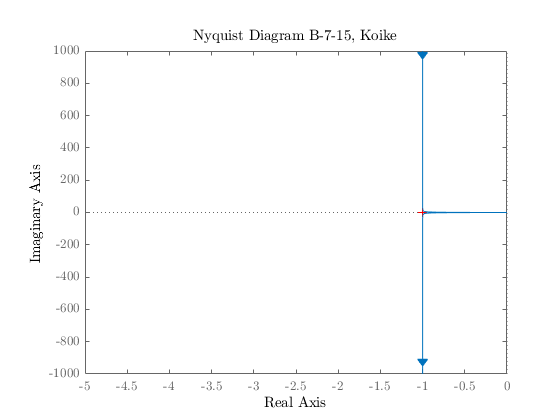


% Nyquist Plot
fig = figure("Renderer","painters");
    opts_nq.Title.String = "Nyquist Diagram B-7-15, Koike";
    opts_nq.Grid = 'off';
    nyquistplot(G,opts_nq);
    xlim([-5 0])
    ylim([-1000 1000])
saveas(fig,fullfile(fdir,"B-7-15_nyquist.png"));

### B-7-19

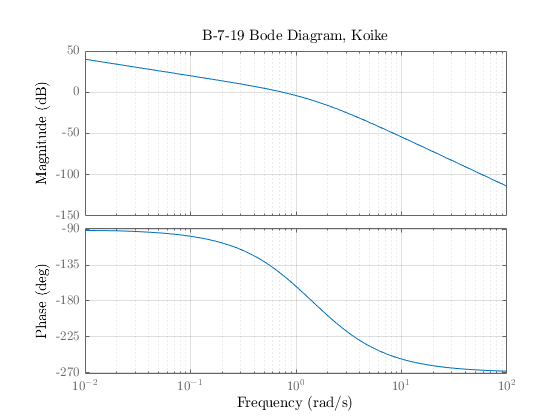

% Define transfer function
num = [0 2];
den = conv([1 0],[1 1]); den = conv(den,[1 2]);
G = tf(num,den);

% Find zeros, poles, and corner frequencies
zrs = roots(num);
pls = roots(den);
cornFreq = corner_freq(num,den);

% Bode Plot
fig = figure("Renderer","painters");
    opts_bd.Title.String = "B-7-19 Bode Diagram, Koike";
    bd = bodeplot(G,opts_bd);
    opt = getoptions(bd);
saveas(fig,fullfile(fdir,"B-7-19_bode.png"));

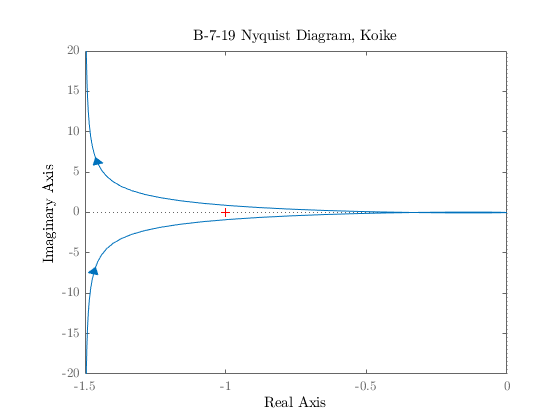


% Sample out points from Bode plot
res = bode_sample_points(G,[0.05,0.2,0.7,1,4,10,15]);
writetable(res,fullfile(fdir,"B-7-19.xls"),"WriteMode","overwritesheet");

% Nyquist Plot 
fig = figure("Renderer","painters");
    opts_nq.Title.String = "B-7-19 Nyquist Diagram, Koike";
    nyquistplot(G,opts_nq);
    opts_nq.Grid = 'off';
saveas(fig,fullfile(fdir,"B-7-19_nyquist.png"));

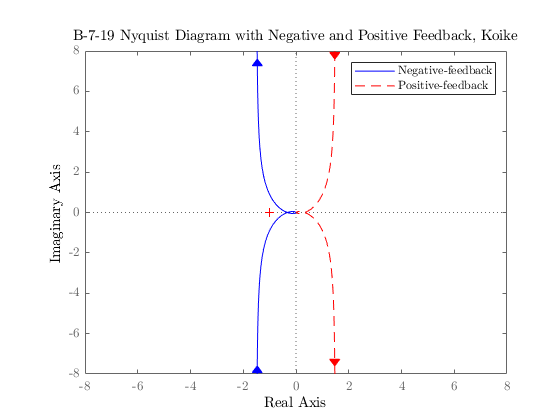


% Nyquist Plot 2
G1 = zpk([],[0, -1, -2],2); % Negative Feedback
G2 = zpk([],[0, -1, -2],-2); % Positive Feedback
fig = figure("Renderer","painters");
    hold on; grid on;
    opts_nq.Title.String = "B-7-19 Nyquist Diagram with Negative and Positive Feedback, Koike";
    nyquistplot(G1,opts_nq, 'blue-')
    nyquistplot(G2,opts_nq, 'red--')
    legend('Negative-feedback', 'Positive-feedback')
    axis equal; xlim([-8,8]);ylim([-8,8]);
saveas(fig,fullfile(fdir,"B-7-19_nyquist2.png"));

### B-7-24

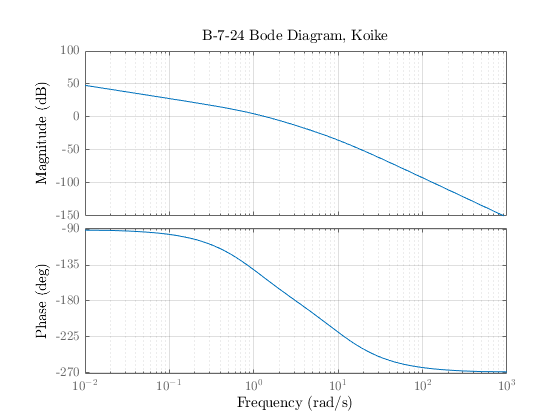

% Define transfer function
num = [0 25];
den = conv([1 0],[1 1]); den = conv(den,[1 10]);
G = tf(num,den);

% Find zeros, poles, and corner frequencies
zrs = roots(num);
pls = roots(den);
cornFreq = corner_freq(num,den);

% Bode Plot
fig = figure("Renderer","painters");
    opts_bd.Title.String = "B-7-24 Bode Diagram, Koike";
    bd = bodeplot(G,opts_bd);
    opt = getoptions(bd);
saveas(fig,fullfile(fdir,"B-7-24_bode.png"));


% Phase Margin 
[Wgc,phi] = gain_crossover(num,den);

Equation of |G(jw)| = 1.


$$625={\left(10\,w-w^{3}\right)}^{2}+121\,w^{4}$$

PM = 180 + phi;

% Gain Margin 
[Wpc,Kg_inv] = phase_crossover(num,den);

The denominator factored out.


$$-1.0\,w^{3}\,\mathrm{i}-11.0\,w^{2}+10.0\,w\,\mathrm{i}$$

The numerator combined with denominator.


$$25.0\,w^{3}\,\mathrm{i}-275.0\,w^{2}-250.0\,w\,\mathrm{i}$$

The imaginary part you need to equate to 0.


$$25.0\,w^{3}-250.0\,w$$

Omegas that make the imaginary part equal 0 (phase crossover frequency).
         0
    3.1623
   -3.1623



GM = 1/abs(Kg_inv);
GM_dB = 20*log10(1/abs(Kg_inv));  % [dB]

% Validate with builtin function
[Gm_v,Pm_v,Wgc_v,Wpc_v] = margin(G);
fprintf("The actual values for relative stability analysis.");

The actual values for relative stability analysis.

fprintf("Gain Margin: %.4f at gain crossover frequency of %.4f",Gm_v,Wgc_v);

Gain Margin: 4.4000 at gain crossover frequency of 3.1623

fprintf("Phase Margin: %.4f at phase crossover frequency of %.4f\n",Pm_v,Wpc_v);

Phase Margin: 26.9973 at phase crossover frequency of 1.4230


### B-7-26

% From phase margin
syms w 
eqn = w == (4 - w^2)*tand(40);
Wgc = double(solve(eqn,w));
Wgc = Wgc(Wgc>0);
K = sqrt(Wgc^6 - 7*Wgc^4 + 16*Wgc^2);

% Define transfer function
num = [0 K];
den = conv([1 0],[1 1 4]);
G = tf(num,den);

% Gain margin
[Wpc,Kg_inv] = phase_crossover(num,den);

The denominator factored out.


$$-1.0\,w^{3}\,\mathrm{i}-1.0\,w^{2}+4.0\,w\,\mathrm{i}$$

The numerator combined with denominator.


$$3.45852\,w^{3}\,\mathrm{i}-3.45852\,w^{2}-13.8341\,w\,\mathrm{i}$$

The imaginary part you need to equate to 0.


$$3.45852\,w^{3}-13.8341\,w$$

Omegas that make the imaginary part equal 0 (phase crossover frequency).
    -2
     0
     2



GM = 1/abs(Kg_inv);
GM_dB = 20*log10(GM); % [dB]

### P3 Aircraft Example

% Define transfer function
num = [1.1057 -0.19];
den = [1 17.95 123.3 366.3 112.2 0];
G = tf(num,den);

pls = roots(den)

pls =    0.0000 + 0.0000i
  -8.0992 + 0.0000i
  -4.7533 + 4.2012i
  -4.7533 - 4.2012i
  -0.3442 + 0.0000i


zrs = roots(num)

zrs = 0.1718

cornFreq = corner_freq(num,den)

cornFreq = 4×2 table
     Poles      Zeros 
    _______    _______

          0    0.17184
    0.34423        NaN
     6.3438        NaN
     8.0992        NaN


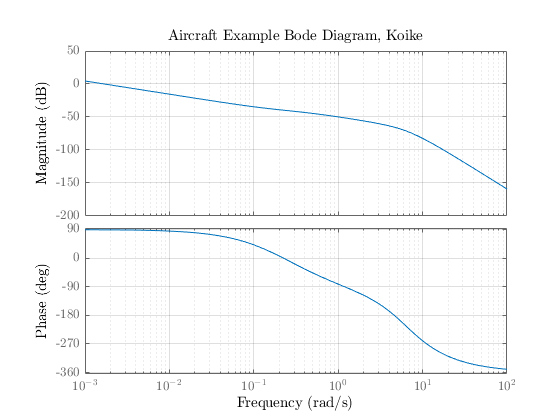


fig = figure("Renderer","painters");
    opts_bd.Title.String = "Aircraft Example Bode Diagram, Koike";
    bodeplot(G,opts_bd);
saveas(fig,fullfile(fdir,"P3_bode.png"));

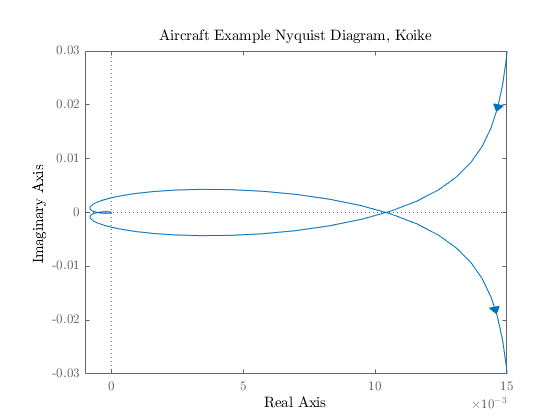

% Sample out points from Bode plot
res = bode_sample_points(G,[0.01,0.1,1,10,50]);
writetable(res,fullfile(fdir,"P3.xls"),"WriteMode","overwritesheet");

% Nyquist Plot 
fig = figure("Renderer","painters");
    opts_nq.Title.String = "Aircraft Example Nyquist Diagram, Koike";
    opts_nq.Grid = 'on';
    nyquistplot(G,opts_nq);
    xlim([-0.001 0.015])
saveas(fig,fullfile(fdir,"P3_nyquist.png"));

### P4 Spacecraft Example

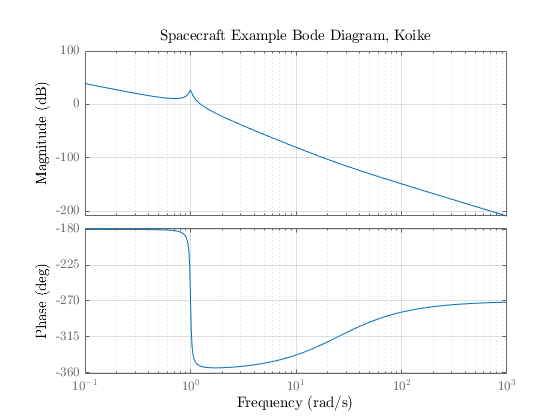

num = 0.036*[1 25];
den = [1 0.04 1 0 0];

pls = roots(den);
zrs = roots(num);
cornFreq = corner_freq(num,den);

G = tf(num,den);
fig = figure("Renderer","painters");
    opts_bd.Title.String = "Spacecraft Example Bode Diagram, Koike";
    bodeplot(G,opts_bd);
saveas(fig,fullfile(fdir,"P4_bode.png"));

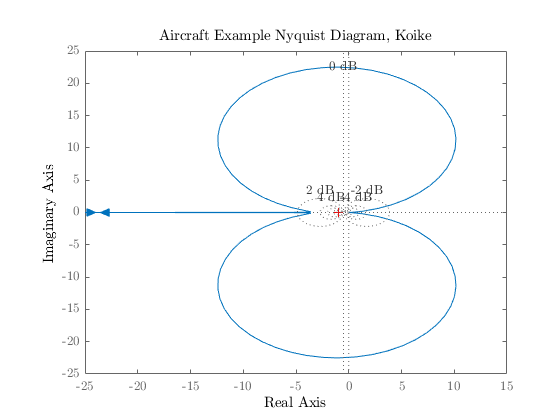

% Sample out points from Bode plot
res = bode_sample_points(G,[0.2,0.7,1,2,10,100,600]);
writetable(res,fullfile(fdir,"P4.xls"),"WriteMode","overwritesheet");

% Nyquist Plot 
fig = figure("Renderer","painters");
    opts_nq.Title.String = "Aircraft Example Nyquist Diagram, Koike";
    nyquistplot(G,opts_nq);
saveas(fig,fullfile(fdir,"P4_nyquist.png"));